Найду PDF каждой спектральной состовляющей для одной ноты. Так найду характеристики Гаусса для Байесовского классификатора

clear all
close all
path = "D:\Desktop\Studie\Diploma\GIT Matlab\Audio data\wav"

path = "D:\Desktop\Studie\Diploma\GIT Matlab\Audio data\wav"

path1 = path + "\Sasha\Steinway Grand Piano 70.wav";
path2 = path + "\Sasha\Yamaha Grand Piano 70.wav";
[y, Fs] = audioread(path1);
z = y(:,1);

% figure
% spectrogram(z,16000, 1000, 16000,Fs,'yaxis')
% title('Sound spectrogram (60 notes)')
% ylim([0 2])

t = [0:length(z)-1]/Fs

t =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011



% figure
% plot(t, z)

Каждая нота играется 2 секунды, после чего следует 2-ух секундная пауза. В итоге каждые 4 секунды звучит новая нота. Возму ноту между 140 и 142 секундами

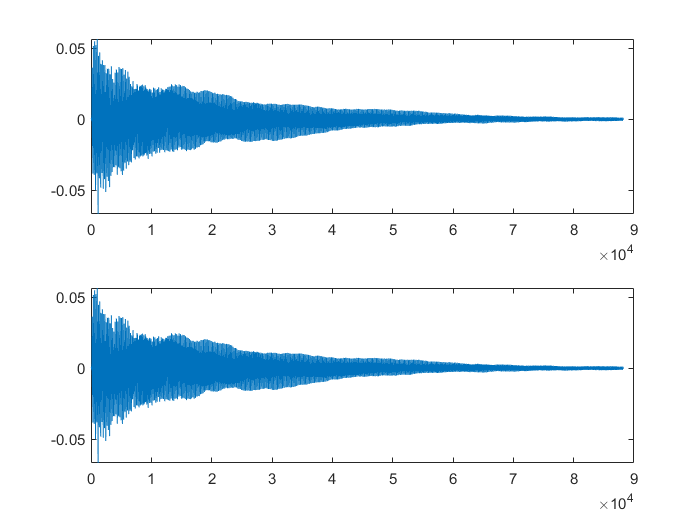

t1 = 140;
t2 = 142;

n1 = t1*Fs;
n2 = t2*Fs;

z1 = z(n1:n2);

figure
title('Проверка')
subplot(2,1,1)
plot(z1)
subplot(2,1,2)
plot(z(n1:n2))

Идея такая. Возьмем 1024-мерный лист и будем складировать в них значения спектра. В итоге после обработки 2ух секунд получим 1024 массива чисел, которые потом уже обработаем и получим их PDF

Samples_num = 1024;
cuts = floor( length(z1) / Samples_num ) - 1;   % Кол-во вырезок по времени
SpecFigures = zeros(1024, cuts);                % Массив векторов

for i = 1:cuts
    
    n1 = i*Samples_num;         % Задаю пределы для вырезания участка сигнала
    n2 = (i+1)*Samples_num - 1;
    
    S = z1(n1: n2);             % Берем участок сигнала
    Spec = abs(fft(S));        % Находим спектр сигнала
    SpecFigures(:,i) = Spec(:);          % Заполняем матрицу нот
    
    if mod(i,200) == 0
        figure(i)
        plot(Spec);
        title("Spectrum number #" + string(i))
    end
    
end

Построение гистограмм для каждой компоненты. Для построения - округлим полученные данные с заданым шагом.

maxH = 20;
vH = [0:cuts-1]*20/cuts;
H = zeros(1024, cuts);

s1 = SpecFigures(6,:)

s1 =    13.5474    8.7737    6.7586    6.2949    6.6592    6.1962    5.2947    4.2854    4.8728    4.8605    4.5109    4.0652    3.9037    4.1360    4.4970    4.2114    3.4830    3.2735    2.9774    3.4051    3.3180    3.1716    2.6133    2.5146    2.4736    2.7309    2.5867    2.2964    1.9635    1.8845    1.9800    2.0715    2.0025    1.5717    1.4698    1.3874    1.5523    1.4961    1.4393    1.0519    1.0859    0.9838    1.1693    1.0526    0.9634    0.7200    0.7245    0.7150    0.8135    0.7177


s2 = SpecFigures(1,:)

s2 =     0.5976    1.6516    0.5164    0.0973    0.0399    0.5876    0.3295    0.7725    0.7549    0.5352    0.4168    0.4306    0.6336    0.2545    0.2749    0.1156    0.3167    0.2118    0.5059    0.0353    0.1266    0.0726    0.3958    0.0910    0.3270    0.1192    0.0682    0.0892    0.2835    0.2245    0.1176    0.1131    0.1545    0.2056    0.1455    0.2574    0.0244    0.0481    0.1304    0.2409    0.0100    0.1713    0.0672    0.0258    0.0104    0.1589    0.0750    0.0917    0.0837    0.0603


s3 = SpecFigures(11,:)

s3 =     7.9950    7.7259    7.6056    7.5920    7.3584    7.2827    7.5955    7.2135    6.5572    6.3973    6.3233    6.0548    5.9048    5.7811    5.1197    4.9667    5.0367    4.9787    4.6383    4.5300    4.2141    4.0754    4.0271    4.0096    3.7600    3.5356    3.3868    3.3685    3.2520    3.1247    3.0304    2.8141    2.6459    2.6836    2.6411    2.4158    2.3599    2.2763    2.1198    2.0936    2.1271    1.9359    1.8276    1.8144    1.7393    1.6484    1.6557    1.5652    1.4509    1.4183


s4 = SpecFigures(15,:)

s4 =     1.8566    1.3274    0.9176    0.3761    0.2247    0.7478    1.4250    1.2848    0.4671    0.0405    0.3312    0.5722    0.8695    0.8643    0.3746    0.0793    0.3688    0.5192    0.5026    0.5134    0.2922    0.2120    0.3274    0.3889    0.3880    0.3176    0.2239    0.2602    0.2870    0.2483    0.3383    0.2716    0.1390    0.1930    0.2525    0.1555    0.2653    0.2742    0.1686    0.0938    0.2044    0.1416    0.1824    0.2301    0.1800    0.0490    0.1560    0.1557    0.1429    0.1601


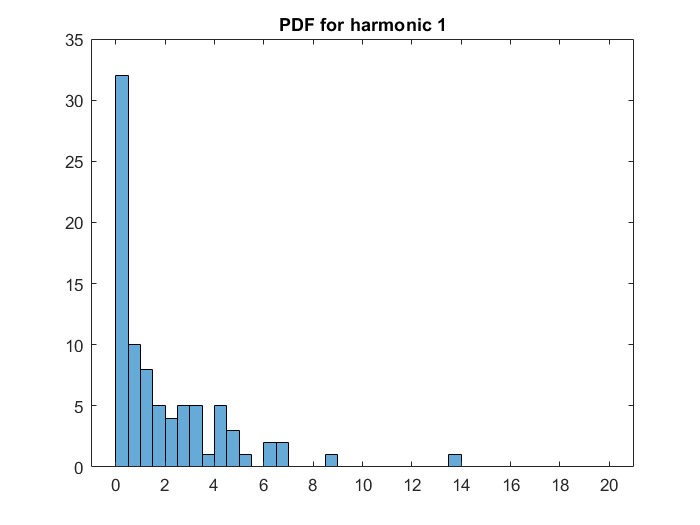


dH = 0.5;
maxH = 20;
edges = [0:dH:maxH];

figure
histogram(s1, edges)
title('PDF for harmonic 1')

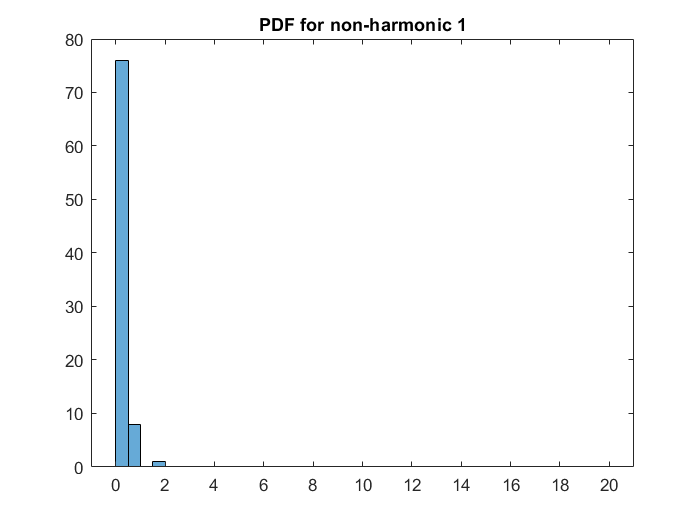


figure
histogram(s2, edges)
title('PDF for non-harmonic 1')

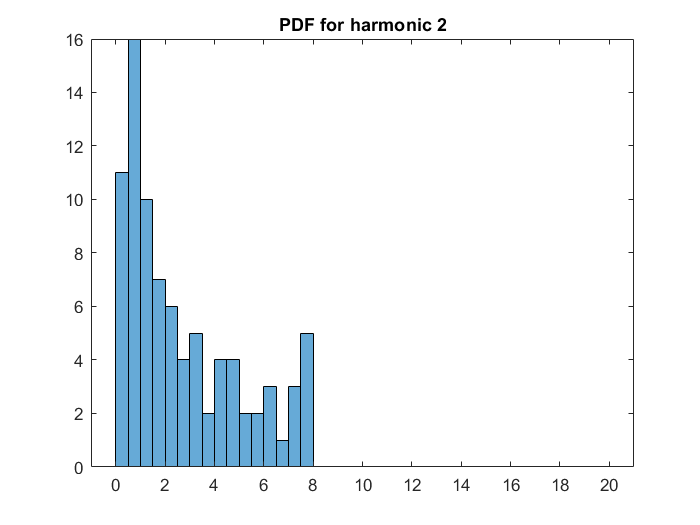


figure
histogram(s3, edges)
title('PDF for harmonic 2')

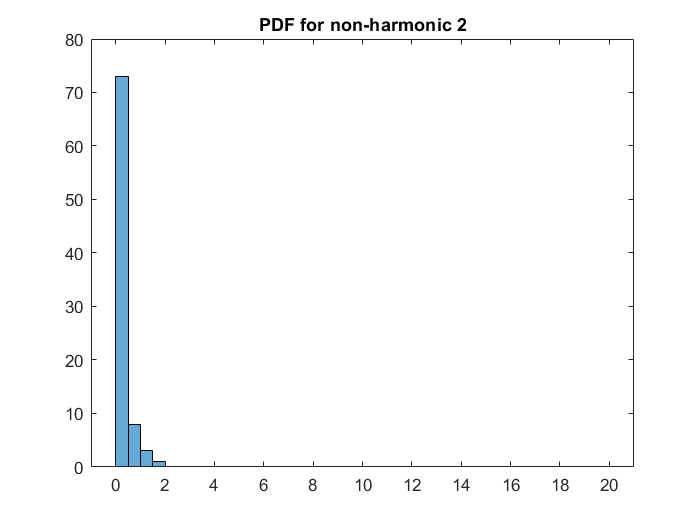


figure
histogram(s4, edges)
title('PDF for non-harmonic 2')


% for j=1:1024
%     
%     s1 = SpecFigures(i,:)
%     pdf_sig = pdf()
%     
% end